# Simulation Setup

wordlen = 14;
fraclen = 12;
Ftype = numerictype('DataType','Fixed',...
    'DataTypeMode','Fixed-point: binary point scaling',...
    'Signedness','Signed',...
    'WordLength',wordlen,...
    'FractionLength',fraclen);
Fmath = fimath('CastBeforeSum', true, 'OverflowAction', 'Wrap',...
    'RoundingMethod','Floor','ProductMode','SpecifyPrecision',...
    'ProductWordLength',wordlen,'ProductFractionLength',fraclen,...
    'SumMode','SpecifyPrecision','SumWordLength',wordlen,'SumFractionLength',fraclen);
one = fi(1, Ftype, Fmath);
zero = fi(0, Ftype, Fmath);

Fc = 1e6; % Carrier frequency in Hz
Fs = 6e6; % Sampling rate
Rs = 50e3; % Symbol rate in symbols/sec (baud)
B = 350e3; % Bandwidth

sps = Fs / Rs; % Number of samples per symbol

msg = 'hello world!';
msg_len_bin = arrayfun(@(x) fi(str2double(x), Ftype, Fmath), dec2bin(length(msg), 8));
msg_bin = arrayfun(@(x) fi(str2double(x), Ftype, Fmath), reshape(dec2bin(msg, 8)', 1, []));

sync_header = reshape(repmat([one zero], 4)', 1, []);

barker_code = [one one one zero zero zero one zero zero one zero];

tail = reshape(repmat([zero one], 2)', 1, []);

bits = [sync_header barker_code msg_len_bin msg_bin tail];

num_symbols = length(bits); % Number of symbols/bits to send
num_samples = num_symbols * sps; % Number of discrete samples

% Use these guys for plotting
t = linspace(0, num_symbols / Rs, num_samples); % Time variable
f = linspace(-Fs/2,Fs/2, num_samples); % Frequency variable
xview = [0.000, 0.003];

% Clear all previous figures before starting
close all;

## Mapping Bits to Symbols

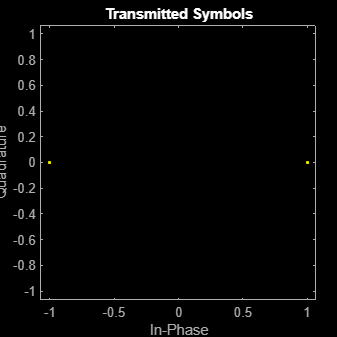

% Convert to BPSK Symbols (1's and -1's)
symbols = bits;
symbols(symbols == zero) = fi(-1, Ftype, Fmath);

% Visualize BPSK Symbols in a Constellation Diagram
scatterplot(double(symbols));
title("Transmitted Symbols");

## Upsample

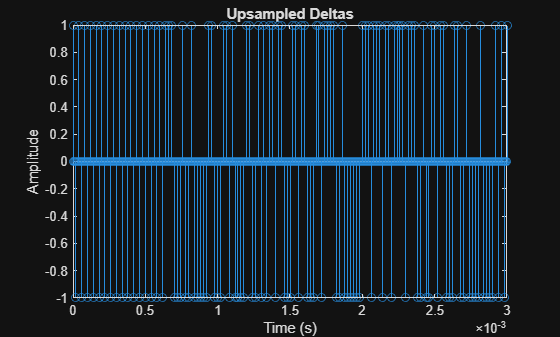

% Use upsample to form a delta train
deltas = upsample(symbols, sps);

% Visualize Deltas (xlimited to only first ~20 symbols)
figure;
stem(t, deltas);
title("Upsampled Deltas");
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

## Pulse Shaping

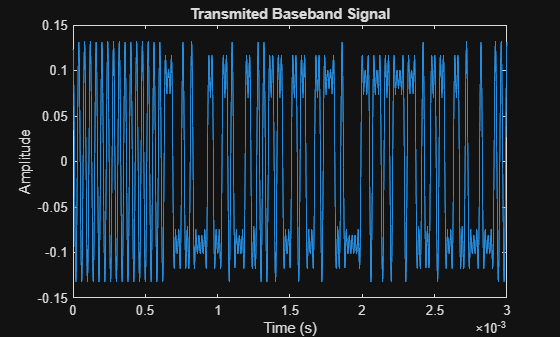

% Use an SRRC as the pulse shape filter
beta = 1; % RRC rolloff factor
span = 3; % number of symbols for length of filter impulse response
ps_filter = rcosdesign(beta, span, sps, 'sqrt');

% Convolve the deltas with the rectangular window
baseband_samples = conv(deltas, ps_filter, 'same');

% Visualize Transmitted Baseband Signal
figure;
plot(t, baseband_samples);
title("Transmited Baseband Signal");
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

## Modulate to Carrier

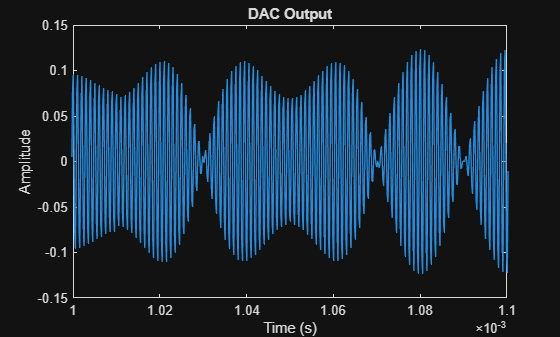

phase_offset = pi;
transmitted_signal = modulate_carrier(double(baseband_samples), Fc, t, phase_offset);

% Upsample to simulate 
sym_factor = 100;

sym_s = Fs * sym_factor;
real_len = length(transmitted_signal);
real_t = linspace(0, real_len / Fs, real_len * sym_factor);
real_samples = conv(upsample(double(transmitted_signal), sym_factor), ...
    designfilt('lowpassfir', 'FilterOrder', 5 * sym_factor, 'CutoffFrequency', 1e6, 'SampleRate', sym_s).Coefficients, ...
    "same");

% for i=1:length(real_samples)
%     if real_samples(i) == 0
%         real_samples(i) = real_samples(i - 1);
%     end
% end

figure;
plot(t, transmitted_signal);
title("DAC Output");
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0.001, 0.0011]);

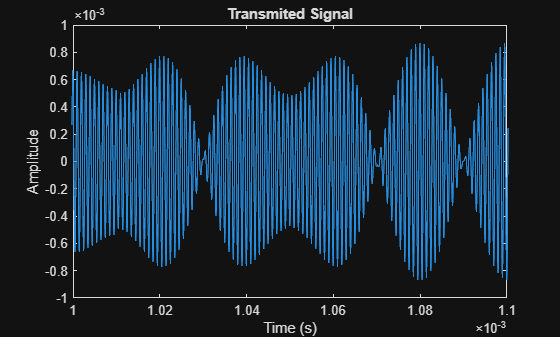


% Visualize Transmitted Signal
figure;
plot(real_t, real_samples);
title("Transmited Signal");
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0.001, 0.0011]);

## Transmit Over Channel

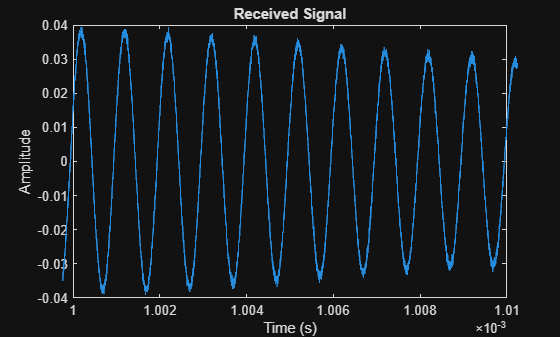

snr = 30;
fixed_gain = 1000;
received_signal = add_channel_impairments(real_samples, B, Fc, sym_s, snr) * fixed_gain;

figure;
plot(real_t, received_signal);
title("Received Signal");
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0.001, 0.00101]);

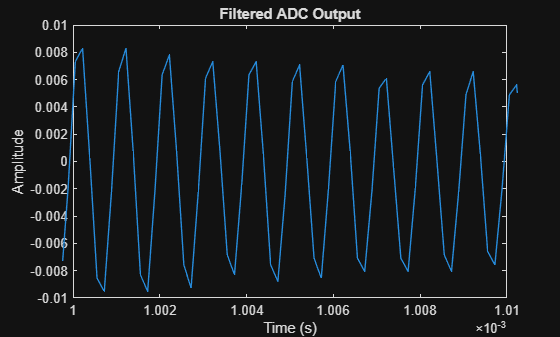


rx_Fs = 3e6;
sampled_signal = fi(downsample(received_signal, (sym_factor) * (Fs / rx_Fs)), Ftype, Fmath);

lowpass = designfilt('lowpassfir', 'FilterOrder', 11, 'CutoffFrequency', 1e6, 'SampleRate', Fs).Coefficients;
filtered_signal = conv(upsample(sampled_signal, Fs / rx_Fs), lowpass, 'same');

% Plot the Received Signal
figure;
plot(t, filtered_signal)
title("Filtered ADC Output")
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0.001, 0.00101]);

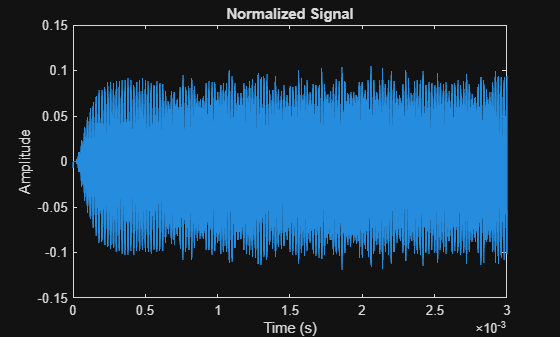



% Normalize the signal for stability of PID tuning constants
AGC_kp = 2^(4);
gain_kp = 2^(-7);
ref = fi(0.1, Ftype, Fmath);
window = 128;
[normalized_signal, gain, err] = AGC(filtered_signal, AGC_kp, gain_kp, ref, window);

figure;
plot(t, normalized_signal)
title("Normalized Signal")
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

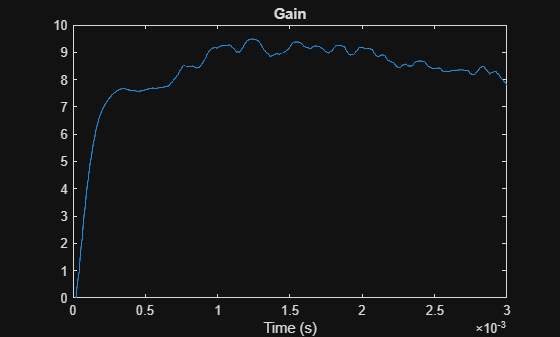



% Plot the Gain
figure;
plot(t, gain)
title("Gain")
xlabel('Time (s)');
xlim(xview);

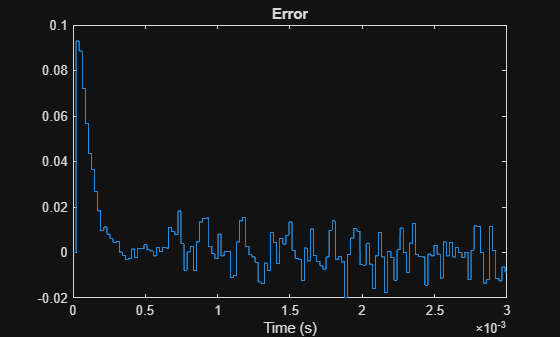


% Plot the Error
figure;
plot(t, err)
title("Error")
xlabel('Time (s)');
xlim(xview);

## Demodulation

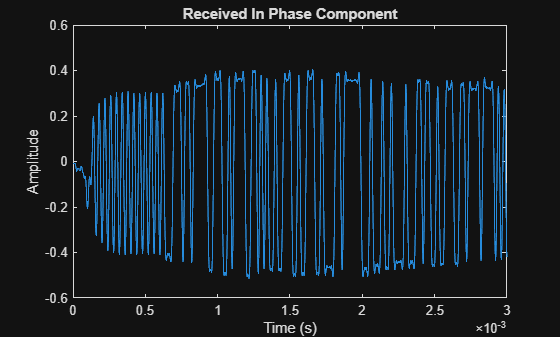

% Encorporate a frequency offset
carrier_frq = Fc + (Fc * 0.03);

% PID Tuning Constants
Kp = 2^(4);
Ki = 2^(-2);
Kd = 2^(-1);
% Costas Loop to extract I and Q components
[I, Q, theta, err, costas_lp] = costas_loop(normalized_signal, carrier_frq, Fs, t, Kp, Ki, Kd, Ftype, Fmath);

I_ps = conv(I, ps_filter, 'same');

figure;
plot(t, I_ps)
title("Received In Phase Component")
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

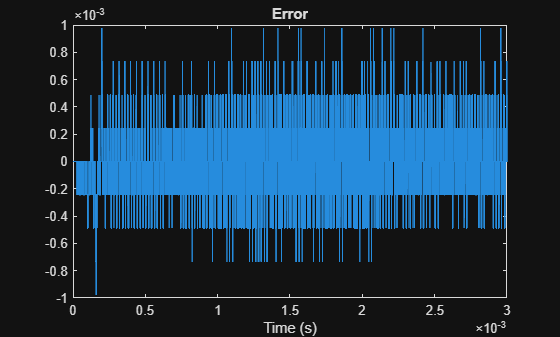


% Plot the Error
figure;
plot(t, err)
title("Error")
xlabel('Time (s)');
xlim(xview);

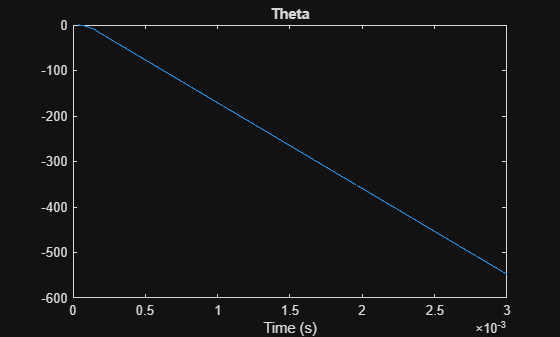


% Plot the Theta
figure;
plot(t, theta(1:length(t)))
title("Theta")
xlabel('Time (s)');
xlim(xview);

## Sample and Detect Symbols

% TODO 1.1: Apply SPS frequency offset at the receiver
sps_offset = sps - 1;

% TODO 1.2: Apply SPS phase offset at the receiver
shift_samples = circshift(I_ps, sps*0.5)

shift_samples =   Columns 1 through 3276
   -0.2319   -0.2285   -0.2244   -0.2202   -0.2139   -0.2100   -0.2051   -0.2000   -0.1956   -0.1907   -0.1865   -0.1824   -0.1785   -0.1741   -0.1699   -0.1646   -0.1604   -0.1553   -0.1504   -0.1458   -0.1421   -0.1384   -0.1340   -0.1299   -0.1255   -0.1211   -0.1165   -0.1130   -0.1099   -0.1060   -0.1013   -0.0972   -0.0945   -0.0920   -0.0876   -0.0852   -0.0828   -0.0786   -0.0764   -0.0747   -0.0713   -0.0686   -0.0654   -0.0635   -0.0610   -0.0588   -0.0566   -0.0544   -0.0530   -0.0518   -0.0505   -0.0481   -0.0452   -0.0427   -0.0410   -0.0398   -0.0383   -0.0374   -0.0364   -0.0339   -0.0051   -0.0049   -0.0049   -0.0049   -0.0051   -0.0051   -0.0054   -0.0056   -0.0061   -0.0061   -0.0061   -0.0061   -0.0063   -0.0066   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0073   -0.0073   -0.0073   -0.0073   -0.0073   -0.0073   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0076   -0.0078   -0.0078   -0.0078   -0.0078   -0.007

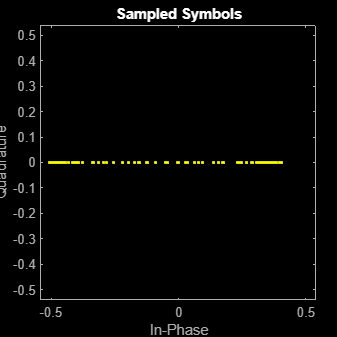


% Naively sample the received signal at the symbol rate to get the received symbols
naive_received_symbols = downsample(shift_samples, sps_offset);

% Visualize the received symbols in a constellation diagram (scatterplot)
scatterplot(double(naive_received_symbols(33:end-11)));
title("Sampled Symbols");


% Normalize for stability for PID stability
% sigma_sqr = 1
% TODO Section 2: Implement one (or multiple) of the timing error detectors to properly sample
% PID Tuning Constants
Kp = 2 % observe how Kp causes faster settling w/o oscillation but increases self-noise effect

Kp = 2

Ki = 0.1 % observe how Ki smooths the oscillations before settling to a constant offset (but eventually goes unstable)

Ki = 0.1000

Kd = 0 % observe how Kd increases high frequency noise in the lock

Kd = 0


% Recreate the downsample function iteratively, then implement the TED

[symbs, phase_offsets] = my_downsample(shift_samples, sps_offset, Kp, Ki, Kd);

% TODO: Visualize the properly receieved samples
% Note: A good chunk of the early symbols might be garbage as the TED locks on, so feel free
%       to only plot the later end of the symbols

mdl = fitlm((length(phase_offsets)-50:length(phase_offsets)),phase_offsets(end-50:end))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)     -0.46517     0.0089706    -51.855    1.7838e-44
    x1             0.0082966    6.7541e-05     122.84    1.1303e-62


Number of observations: 51, Error degrees of freedom: 49
Root Mean Squared Error: 0.0071
R-squared: 0.997,  Adjusted R-Squared: 0.997
F-statistic vs. constant model: 1.51e+04, p-value = 1.13e-62

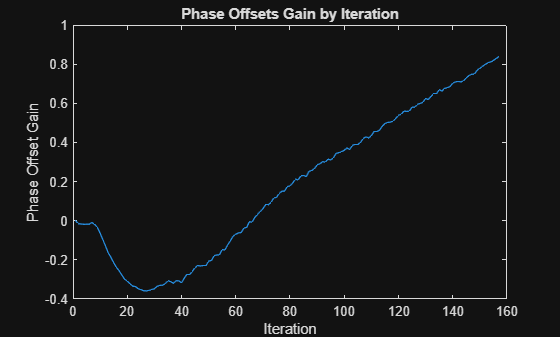


figure;
plot(1:length(phase_offsets), phase_offsets);
title("Phase Offsets Gain by Iteration")
xlabel('Iteration');
ylabel('Phase Offset Gain');

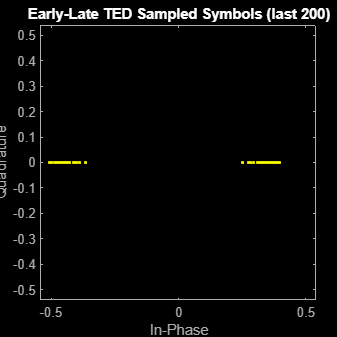


scatterplot(symbs(33:end-11));
title("Early-Late TED Sampled Symbols (last 200)")


% TODO: You'll probably want to change this once you have the timing error detector
received_symbols = symbs;

% Apply Thresholding to detect the symbols (turning them back to 1's and -1's)
received_symbols(received_symbols > 0) = 1;
received_symbols(received_symbols <= 0) = 0;

## Detect Message

bcode_len = length(barker_code);
msg_start = 0;
for i=1:(length(received_symbols)-bcode_len)
    if all(~xor(barker_code, received_symbols(i:i+bcode_len-1)))
        msg_start = i+bcode_len;
        break;
    elseif all(xor(barker_code, received_symbols(i:i+bcode_len-1)))
        received_symbols = ~received_symbols;
        msg_start = i+bcode_len;
        break;
    end
end
msg_len = bin2dec(num2str(received_symbols(msg_start:msg_start+7), '%1d'));
rx_bits = received_symbols(msg_start+8:msg_start+7+(8*msg_len));
rx_msg = char(bin2dec(reshape(num2str(rx_bits, '%1d'), 8, []).')).'

rx_msg = 'hello world!'

## Generate Verilog Memory Files

% To be read in verilog using the readmemh directive
% fixed_rrcos = fi(ps_filter.', Ftype, Fmath);
% fixed_upsample_lowpass = fi(lowpass.', Ftype, Fmath);
Ftype_costas = numerictype('DataType','Fixed',...
    'DataTypeMode','Fixed-point: binary point scaling',...
    'Signedness','Signed',...
    'WordLength',32,...
    'FractionLength',16);
costas_lp = fi(designfilt('lowpassfir', 'FilterOrder', 7, 'CutoffFrequency', 1.25e6, 'SampleRate', Fs).Coefficients.', Ftype_costas, Fmath);
writematrix(costas_lp.bin, "costas_lp.mem", "FileType","text", "QuoteStrings","none", "Delimiter",' ');
% writematrix(fixed_upsample_lowpass.bin, "upsample_lp.mem", "FileType","text", "QuoteStrings","none", "Delimiter",' ');
% writematrix(fixed_rrcos.bin, "psfilt.mem", "FileType","text", "QuoteStrings","none", "Delimiter",' ');